**编译环境 Matlab R2022a**

**低版本可能导致编译失败**

**特别注意：本代码是对数据特化的代码**

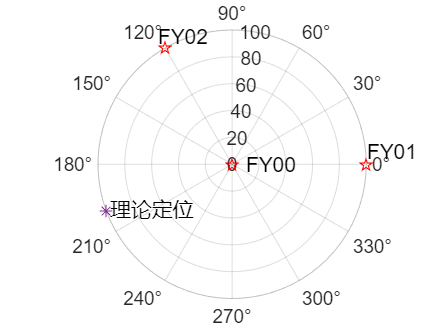

thetaA = deg2rad(0);
rhoA = 100;
thetaB = deg2rad(120);
rhoB = 100;
figure
polarplot(thetaA,rhoA,"rp");
hold on;
polarplot(thetaB,rhoB,"rp");
hold on;
polarplot(0,0,"rp");
hold on;
polarplot(deg2rad(200),100,"*");
hold on;
text(thetaA+0.1,rhoA+1,"FY01");
text(thetaB,rhoB+10,"FY02");
text(0,10,"FY00");
text(deg2rad(200),100-3,"理论定位");

极坐标转换至直角坐标系

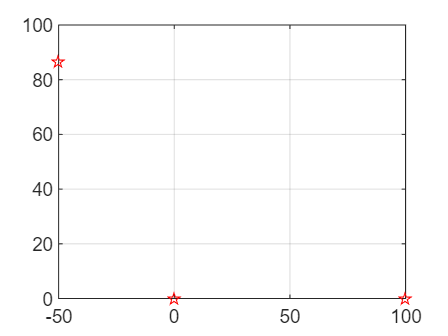

figure
x1=0;y1=0;
x2=rhoA.*cos(thetaA);y2=rhoA.*sin(thetaA);
x3=rhoB.*cos(thetaB);y3=rhoB.*sin(thetaB);
plot(x1,y1,"rp",x2,y2,"rp",x3,y3,"rp");

grid on;

角度处理

angle1=10;
angle2=50;
angle3=60;
if(angle1>180)
    angle1=360-angle1;
end
if(angle2>180)
    angle2=360-angle2;
end
if(angle3>180)
    angle3=360-angle3;
end
if(angle1>90)
    angle1=180-angle1;
end
if(angle2>90)
    angle2=180-angle2;
end
if(angle3>90)
    angle3=180-angle3;
end

绘制线段

line([x1,x2],[y1,y2]);
line([x1,x3],[y1,y3]);
line([x2,x3],[y2,y3]);
hold on;

求圆1

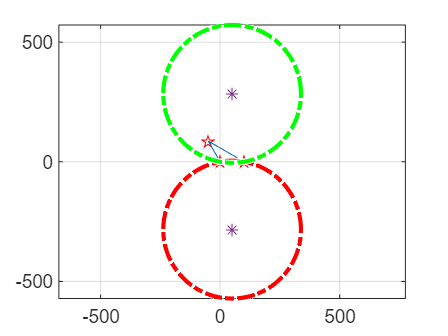

syms x y xa xb ya yb l;
l=sqrtm((x1-x2)^2+(y1-y2)^2)/2/sin(deg2rad(angle1));
xa=x1;xb=x2;ya=y1;yb=y2;
equ1=(x-xa)^2+(y-ya)^2==(x-xb)^2+(y-yb)^2;
equ2=(x-xa)^2+(y-ya)^2==l^2;
[x,y]=solve(equ1,equ2,x,y);
plot(x,y,'*');
axis equal;
viscircles([double(x(1,1)) double(y(1,1))],l,'Color','r','LineStyle','-.');
viscircles([double(x(2,1)) double(y(2,1))],l,'Color','g','LineStyle','-.');
hold on;

o1x=double(x(1,1));o1y=double(y(1,1));
r1=l;
clear x y xa xb ya yb l;

求圆2

syms x y xa xb ya yb l equ1 equ2;
l=sqrtm((x1-x3)^2+(y1-y3)^2)/2/sin(deg2rad(angle2));
xa=x1;xb=x3;ya=y1;yb=y3;
equ1=(x-xa)^2+(y-ya)^2==(x-xb)^2+(y-yb)^2;
equ2=(x-xa)^2+(y-ya)^2==l^2;
[x,y]=solve(equ1,equ2,x,y);
plot(x,y,'*')
axis equal;
viscircles([double(x(2,1)) double(y(2,1))],l,'Color','r','LineStyle','-.');
viscircles([double(x(1,1)) double(y(1,1))],l,'Color','g','LineStyle','-.');
hold on;
o2x=double(x(2,1));o2y=double(y(2,1));
r2=l;
clear x y xa xb ya yb l;

求圆3

syms x y xa xb ya yb l equ1 equ2;
l=sqrtm((x2-x3)^2+(y2-y3)^2)/2/sin(deg2rad(angle3));
xa=x2;xb=x3;ya=y2;yb=y3;
equ1=(x-xa)^2+(y-ya)^2==(x-xb)^2+(y-yb)^2;
equ2=(x-xa)^2+(y-ya)^2==l^2;
[x,y]=solve(equ1,equ2,x,y);
plot(x,y,'*')
axis equal;
viscircles([double(x(2,1)) double(y(2,1))],l,'Color','g','LineStyle','-.');
viscircles([double(x(1,1)) double(y(1,1))],l,'Color','r','LineStyle','-.');
o3x=double(x(1,1));o3y=double(y(1,1));
r3=l;
clear x y xa xb ya yb l;

绘制交点

syms ax ay;
equ1=(ax-o1x)^2+(ay-o1y)^2==r1^2;
equ2=(ax-o2x)^2+(ay-o2y)^2==r2^2;
equ3=(ax-o3x)^2+(ay-o3y)^2==r3^2;
[ax1,ay1]=solve(equ1,equ2,ax,ay);
[ax2,ay2]=solve(equ1,equ3,ax,ay);
[ax3,ay3]=solve(equ2,equ3,ax,ay);
axx=(ax1(1,1)+ax2(1,1)+ax3(1,1))/3;
ayy=(ay1(1,1)+ay2(1,1)+ay3(1,1))/3;
plot(axx,ayy,'p');

绘图全局设置

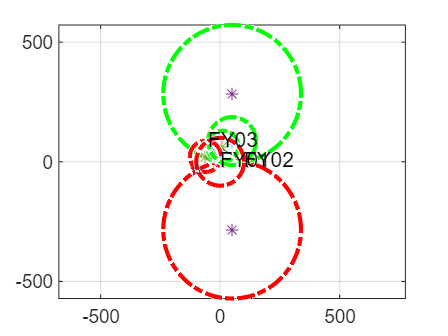

text(x1,y1+10,"FY01");
text(x2,y2+10,"FY02");
text(x3,y3+10,"FY03");
grid on

直角坐标转换至极坐标系并绘制

ar=vpa(sqrtm(axx^2+ayy^2))

$$ar = 99.999999999999994223301433553162$$

at=vpa(atand(ayy/axx))+180

$$at = 200.00000000000000841398448525505$$

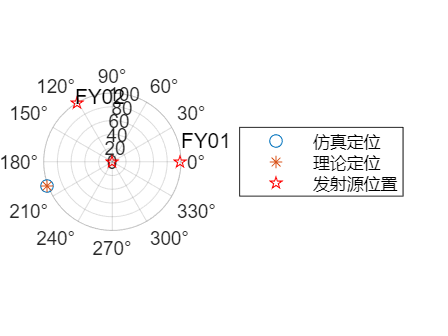


if(at<0)
    at=at+180
end

figure
polarplot(deg2rad(at),ar,"o");
hold on;
polarplot(deg2rad(200),100,"*");
polarplot(thetaA,rhoA,"rp");
polarplot(thetaB,rhoB,"rp");
polarplot(0,0,"rp");
text(thetaA+0.3,rhoA+5,"FY01");
text(thetaB,rhoB+10,"FY02");

legend('仿真定位', '理论定位', '发射源位置');